# `Clear Section`

clear
close all
clc

# `BPSK`

## Generate data bit stream

number_of_bits = 1000000;                   % number of transmitted bits
amplitude = 1;                           % amp;itude of transmitted signal
bits = randi([0 1], 1, number_of_bits);  % generate random bits
Tx_Data = amplitude*(2*bits-1);          % converete to polar code

## Add AWGN from Channel

Eb = 1;                                              % energy of bit
SNR = -2:1:20;                                       % SNR valus 
No = Eb./(10.^(SNR/10));                             % variance value of noise
noise = (sqrt(No/2))'.*randn(1, number_of_bits);     % generate noise with zero mean and No/2 variance
var(noise(1, :));

## ِAdd Noise to Tx data

Rx_Data = Tx_Data + noise;                           % adding noise to Tx data

## BER Calculations

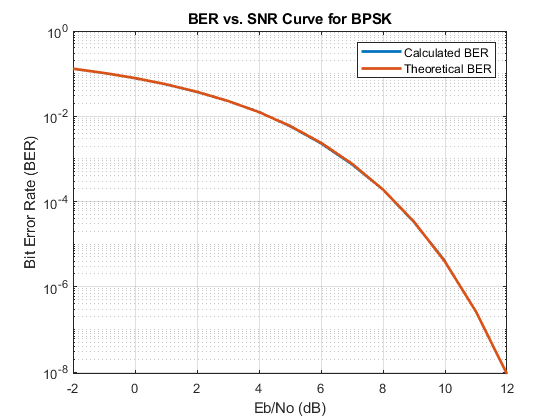

BER_Calculated_BPSK = zeros(1, length(SNR));
BER_Theoretical = 0.5*erfc(sqrt(Eb./No));
for i = 1 : length(SNR)
    BER_Calculated_BPSK(1, i) = (sum(sign(Rx_Data(i, :)) ~= Tx_Data))/number_of_bits;
end
BER_Calculated_BPSK;
%subplot(2, 1, 1)
semilogy(SNR, BER_Calculated_BPSK, 'LineWidth', 2)
xlim([-2 12])
hold on
semilogy(SNR, BER_Theoretical, 'LineWidth', 2)
xlabel("Eb/No (dB)")
ylabel("Bit Error Rate (BER)")
title("BER vs. SNR Curve for BPSK")
legend("Calculated BER", "Theoretical BER")
grid on
hold off

# `QPSK`

## Generate data bit stream

number_of_bits = 1000000;                % number of transmitted bits
M = 4;                                   % number of symbols
amplitude = 1;                           % amp;itude of transmitted signal
bits = randi([0 1], 1, number_of_bits);  % generate random bits
Data = amplitude*(2*bits-1);             % converete to polar code
real_part = Data(1, 1:2:end);            % get real part
imaginary = Data(1, 2:2:end);            % get imaginary part
Tx_Data = (real_part+1j*imaginary);      % determine Tx data

## Add AWGN from Channel

Eb = 1;                                              % energy of bit
SNR = -2:1:20;                                       % SNR values 
No = Eb./(10.^(SNR/10));                             % variance value of noise
noise = (sqrt(No/2))'.*randn(1, number_of_bits/2) + 1j*(sqrt(No/2))'.*randn(1, number_of_bits/2);    % generate noise with zero mean and No/2 variance

## Add Noise to Tx data

Rx_Data = Tx_Data + noise;                           % adding noise to Tx data

## BER Calculations

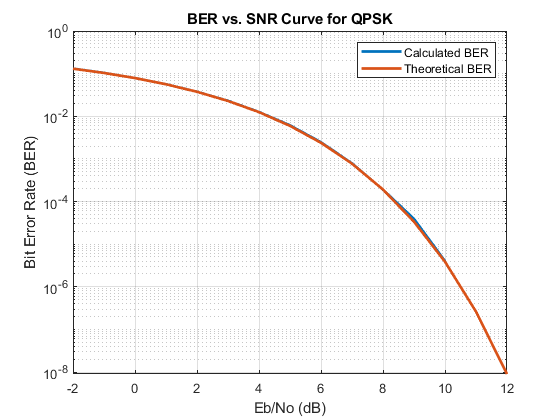

BER_Calculated_QPSK = zeros(1, length(SNR));
BER_Theoretical_QPSK = 0.5*erfc(sqrt(Eb./No));
R = real(Rx_Data);
I = imag(Rx_Data);
extract_Data(1:size(R, 1), 1:2:2*size(R, 2)) = R;
extract_Data(1:size(I, 1), 2:2:2*size(I, 2)) = I;
for i = 1 : length(SNR)
    BER_Calculated_QPSK(1, i) = (sum(sign(extract_Data(i, :)) ~= Data))/number_of_bits;
end
BER_Calculated_QPSK;
%subplot(2, 1, 1)
semilogy(SNR, BER_Calculated_QPSK, 'LineWidth', 2)
xlim([-2 12])
hold on
semilogy(SNR, BER_Theoretical_QPSK, 'LineWidth', 2)
xlabel("Eb/No (dB)")
ylabel("Bit Error Rate (BER)")
title("BER vs. SNR Curve for QPSK")
legend("Calculated BER", "Theoretical BER")
grid on
hold off

## SER Calculations

SER_Calculated_QPSK = zeros(1, length(SNR));
%%%%%%%%%%%%%%%%%%%% Direct Calculation from BER %%%%%%%%%%%%%%%%%%%% 
% SER_Calculated_QPSK = 2*BER_Calculated_QPSK - BER_Calculated_QPSK.^2
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for i = 1 : length(SNR)
    SER_Calculated_QPSK(1, i) = sum(quadrant_number(Rx_Data(i, :)) ~= quadrant_number(Tx_Data))/(number_of_bits/log2(M));
end
SER_Calculated_QPSK;
BER_Calculated_QPSK;

# `8PSK`

## Generate data bit stream

number_of_bits = 1000000-1;                % number of transmitted bits
M = 8;                                   % number of symbols
amplitude = 1;                           % amp;itude of transmitted signal
bits = randi([0 1], 1, number_of_bits);  % generate random bits
% Data = amplitude*(2*bits-1)            % converete to polar code
Tx_Data = mapping_8PSK(bits);            % determine Tx data

## Add AWGN from Channel

M = 8;
bits = log2(M);
Eb = 1;
E = Eb*bits;
SNR = -2:1:20;                                       % SNR values 
No = Eb./(10.^(SNR/10));                             % variance value of noise
noise = (sqrt(No/2))'.*randn(1, number_of_bits/bits) + 1j*(sqrt(No/2))'.*randn(1, number_of_bits/bits);    % generate noise with zero mean and No/2 variance

## Add Noise to Tx data

Rx_Data = Tx_Data + noise;                           % adding noise to Tx data

## SER Calculations

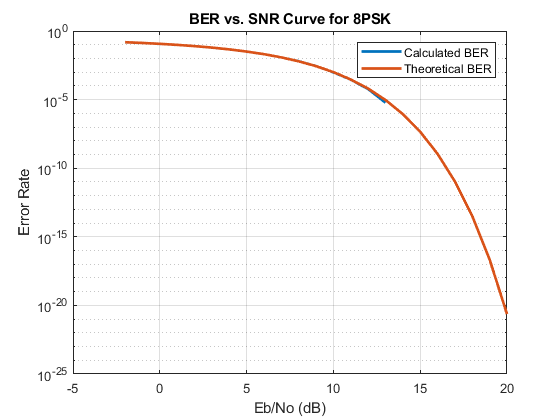

SER_Theoretical_8PSK = erfc(sqrt(E./No)*sin(pi/M));
SER_Calculated_8PSK = zeros(1, length(SNR));
for i = 1 : length(SNR)
    SER_Calculated_8PSK(1, i) = angle_8PSK(Tx_Data, Rx_Data(i, :))/(number_of_bits/log2(M));
end
BER_Calculated_8PSK = SER_Calculated_8PSK/bits; 
BER_Theoretical_8PSK = SER_Theoretical_8PSK/bits;
SER_Calculated_8PSK;
SER_Theoretical_8PSK;
semilogy(SNR, BER_Calculated_8PSK, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Theoretical_8PSK, 'LineWidth', 2)
xlabel("Eb/No (dB)")
ylabel("Error Rate")
title("BER vs. SNR Curve for 8PSK")
legend("Calculated BER", "Theoretical BER")
grid on
hold off

# `16QAM`

# `Comparison`

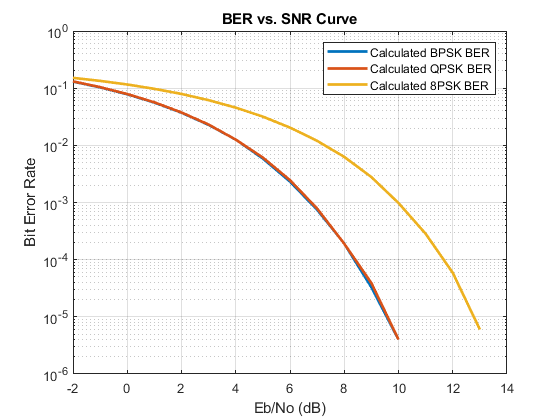

semilogy(SNR, BER_Calculated_BPSK, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Calculated_QPSK, 'LineWidth', 2)
hold on
semilogy(SNR, BER_Calculated_8PSK, 'LineWidth', 2)
xlabel("Eb/No (dB)")
ylabel("Bit Error Rate")
title("BER vs. SNR Curve")
legend("Calculated BPSK BER", "Calculated QPSK BER", "Calculated 8PSK BER")%, "Calculated QPSK SER")
grid on
hold off

# `Useful Functions    `

## `Determine quadrant number`

function y = quadrant_number(x)
    for i = 1 : length(x)
        if real(x(i)) > 0
            if imag(x(i)) > 0
                y(i) = 1;
            else
                y(i) = 4;
            end
        else
            if imag(x(i)) > 0
                y(i) = 2;
            else
                y(i) = 3;
            end
        end
    end
end

## `Mapping to 8PSK`

function y = mapping_8PSK(x)
    M = 8;
    bits = log2(M);
    Eb = 1;
    E = bits*Eb;
    split_x = reshape(x, bits, length(x)/bits)';
    y = size(length(split_x), 1);
    for i = 1:size(split_x, 1)
        if split_x(i, 1) == 0 && split_x(i, 2) == 0 && split_x(i, 3) == 0
            y(i)=sqrt(E)*exp(1j*0);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 0 && split_x(i, 3) == 1
            y(i)=sqrt(E)*exp(1j*pi/4);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 1 && split_x(i, 3) == 1
            y(i)=sqrt(E)*exp(1j*pi/2);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 1 && split_x(i, 3) == 1
            y(i)=sqrt(E)*exp(1j*3*pi/4);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 0 && split_x(i, 3) == 1
            y(i)=sqrt(E)*exp(1j*pi);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 0 && split_x(i, 3) == 0
            y(i)=sqrt(E)*exp(1j*5*pi/4);
        end
        if split_x(i, 1) == 1 && split_x(i, 2) == 1 && split_x(i, 3) == 0
            y(i)=sqrt(E)*exp(1j*3*pi/2);
        end
        if split_x(i, 1) == 0 && split_x(i, 2) == 1 && split_x(i, 3) == 0
            y(i)=sqrt(E)*exp(1j*7*pi/4);
        end
    end
end

## `Determine Angle of sympol in 8PSK number`

function incorrecr_bits = angle_8PSK(Tx, Rx)
    Tx_angles = rad2deg(mod(angle(Tx), 2*pi));   
    Rx_angles = rad2deg(mod(angle(Rx), 2*pi));
    Tx_sympols = zeros(1, length(Tx));
    Rx_sympols = zeros(1, length(Rx));
    for i = 1 : length(Tx_angles)
        if (Tx_angles(i) >= 0 && Tx_angles(i) < 22.5) || (Tx_angles(i) >= 337.5 && Tx_angles(i) < 360)
            Tx_sympols(i) = 1;
        end
        if (Tx_angles(i) >= 22.5 && Tx_angles(i) < 67.5)  
            Tx_sympols(i) = 2;
        end
        if (Tx_angles(i) >= 67.5 && Tx_angles(i) < 112.5)
            Tx_sympols(i) = 3;
        end
        if (Tx_angles(i) >= 112.5 && Tx_angles(i) < 157.5)
            Tx_sympols(i) = 4;
        end
        if (Tx_angles(i) >= 157.5 && Tx_angles(i) < 202.5)
            Tx_sympols(i) = 5;
        end
        if (Tx_angles(i) >= 202.5 && Tx_angles(i) < 247.5)
            Tx_sympols(i) = 6;
        end
        if (Tx_angles(i) >= 247.5 && Tx_angles(i) < 292.5)
            Tx_sympols(i) = 7;
        end
        if (Tx_angles(i) >= 292.5 && Tx_angles(i) < 337.5)
            Tx_sympols(i) = 8;
        end        
    end

    for i = 1 : length(Rx_angles)
        if (Rx_angles(i) >= 0 && Rx_angles(i) < 22.5) || (Rx_angles(i) >= 337.5 && Rx_angles(i) < 360)
            Rx_sympols(i) = 1;
        end
        if (Rx_angles(i) >= 22.5 && Rx_angles(i) < 67.5)  
            Rx_sympols(i) = 2;
        end
        if (Rx_angles(i) >= 67.5 && Rx_angles(i) < 112.5)
            Rx_sympols(i) = 3;
        end
        if (Rx_angles(i) >= 112.5 && Rx_angles(i) < 157.5)
            Rx_sympols(i) = 4;
        end
        if (Rx_angles(i) >= 157.5 && Rx_angles(i) < 202.5)
            Rx_sympols(i) = 5;
        end
        if (Rx_angles(i) >= 202.5 && Rx_angles(i) < 247.5)
            Rx_sympols(i) = 6;
        end
        if (Rx_angles(i) >= 247.5 && Rx_angles(i) < 292.5)
            Rx_sympols(i) = 7;
        end
        if (Rx_angles(i) >= 292.5 && Rx_angles(i) < 337.5)
            Rx_sympols(i) = 8;
        end        
    end    
    incorrecr_bits = sum(Rx_sympols ~= Tx_sympols);
end
